clc
clear
close all

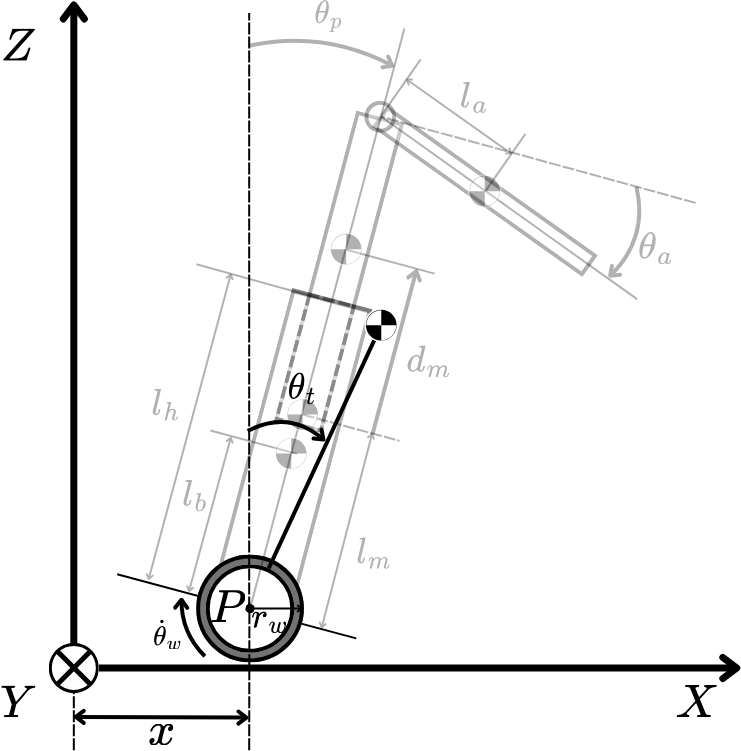

syms t g rw lt th_t(t) dth_t ddth_t th_w(t) dth_w ddth_w mw mt Iw nw tau_w


% Rotation matrices for theta_p and theta_a

Rt = simplify([cos(pi/2-th_t(t)) -sin(pi/2-th_t(t));
      sin(pi/2-th_t(t)) cos(pi/2-th_t(t))]);


% Linear velocity robot
v = [diff(th_w(t))*rw; 0];


% --Wheels--

% Linear velocity
vw = v;

% Angular velocity
ww = v(1)/rw;

% Generalized velocity vector
vtw = [vw; ww];

% Unified inertia
Itw = 2*[mw 0 0;
         0 mw 0;
         0 0 Iw];

% Kinetic energy
Kw = 1/2*vtw.'*Itw*vtw;


% --Body--

% CoG coordinates w.r.t. P
Gt = Rt*[lt; 0];
% Angular velocity
wt = diff(th_t);

% Linear velocity
vt = vw+diff(Gt);

% Generalized velocity vector
vtb = [vt; wt];

% Unified inertia
I = [mt 0 0;
     0 mt 0;
     0 0 mt*lt^2];

% Kinetic energy
Kt = simplify(1/2*vtb.'*I*vtb)

$$Kt(t) = \mathrm{mt}\,{\mathrm{lt}}^{2}\,{\left(\frac{\partial }{\partial t}{\mathrm{th}}_{t}\left(t\right)\right)}^{2}+\frac{\mathrm{mt}\,{\mathrm{rw}}^{2}\,{\left(\frac{\partial }{\partial t}{\mathrm{th}}_{w}\left(t\right)\right)}^{2}}{2}+\mathrm{mt}\,\cos\left({\mathrm{th}}_{t}\left(t\right)\right)\,\mathrm{lt}\,\mathrm{rw}\,\frac{\partial }{\partial t}{\mathrm{th}}_{w}\left(t\right)\,\frac{\partial }{\partial t}{\mathrm{th}}_{t}\left(t\right)$$


% Potential energy
Ut = mt*g*Gt(2)

$$Ut = g\,\mathrm{lt}\,\mathrm{mt}\,\cos\left({\mathrm{th}}_{t}\left(t\right)\right)$$



%--Total Energy--

% Total U
U = Ut;

%Total K
K = simplify(expand(Kw+Kt));


%--Lagrangian--
L = K - U;

% Generalized coordinates
q = [th_w(t), th_t(t)];
dq = [dth_w, dth_t];
ddq = [ddth_w, ddth_t];

% Preallocate vectors for dL_dq and dL_dt
dL_dq = sym(zeros(length(q), 1)); % Partial derivatives of L w.r.t. q
dL_dt = sym(zeros(length(q), 1)); % Time derivatives of partial derivatives of L w.r.t. dq

% Compute derivatives
for i = 1:length(q)
    % Partial derivative of L with respect to q(i)
    dL_dq(i) = collect(diff(L, q(i)),[diff(q,2), diff(q), q]);
    
    % Partial derivative of L with respect to dq(i)
    dL_ddq = diff(L, diff(q(i)));
    
    % Time derivative of the above partial derivative
    dL_dt(i) = collect(diff(dL_ddq, t),[diff(q,2), diff(q), q]);
end

% Generalized torques
tau = [nw*tau_w; -nw*tau_w];

% Euler-Lagrange equation
EL_eq = dL_dt-dL_dq == tau

$$EL\_eq = \begin{array}{l} \left(\begin{array}{c} \left(2\,\mathrm{Iw}+\mathrm{mt}\,{\mathrm{rw}}^{2}+2\,\mathrm{mw}\,{\mathrm{rw}}^{2}\right)\,\sigma_{1}-\mathrm{lt}\,\mathrm{mt}\,\mathrm{rw}\,\sin\left({\mathrm{th}}_{t}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}{\mathrm{th}}_{t}\left(t\right)\right)}^{2}+\mathrm{lt}\,\mathrm{mt}\,\mathrm{rw}\,\cos\left({\mathrm{th}}_{t}\left(t\right)\right)\,\sigma_{2}=\mathrm{nw}\,\tau_{w}\\ 2\,\mathrm{mt}\,{\mathrm{lt}}^{2}\,\sigma_{2}+\mathrm{mt}\,\mathrm{rw}\,\cos\left({\mathrm{th}}_{t}\left(t\right)\right)\,\mathrm{lt}\,\sigma_{1}-g\,\mathrm{mt}\,\sin\left({\mathrm{th}}_{t}\left(t\right)\right)\,\mathrm{lt}=-\mathrm{nw}\,\tau_{w} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial^{2}}{\partial t^{2}}{\mathrm{th}}_{w}\left(t\right)\\ \sigma_{2}=\frac{\partial^{2}}{\partial t^{2}}{\mathrm{th}}_{t}\left(t\right) \end{array}$$


% Find inertia matrix
M = subs(EL_eq,[diff(q,2), diff(q), g],[ddq, zeros(1,length(q)), 0]);
M = equationsToMatrix(M,ddq);
M = collect(simplify(expand(M)),[mw mt Iw])

$$M = \left(\begin{array}{cc} \left(2\,{\mathrm{rw}}^{2}\right)\,\mathrm{mw}+{\mathrm{rw}}^{2}\,\mathrm{mt}+2\,\mathrm{Iw} & \left(\mathrm{lt}\,\mathrm{rw}\,\cos\left({\mathrm{th}}_{t}\left(t\right)\right)\right)\,\mathrm{mt}\\ \left(\mathrm{lt}\,\mathrm{rw}\,\cos\left({\mathrm{th}}_{t}\left(t\right)\right)\right)\,\mathrm{mt} & \left(2\,{\mathrm{lt}}^{2}\right)\,\mathrm{mt} \end{array}\right)$$


% Find coriolis and centripetal matrix
H = lhs(subs(EL_eq,[diff(q,2), diff(q), g],[zeros(1,length(q)), diff(q), 0]));
H = simplify(expand(H))

$$H = \left(\begin{array}{c} -\mathrm{lt}\,\mathrm{mt}\,\mathrm{rw}\,\sin\left({\mathrm{th}}_{t}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}{\mathrm{th}}_{t}\left(t\right)\right)}^{2}\\ 0 \end{array}\right)$$


% Find gravitational matrix
G = lhs(subs(EL_eq,[diff(q,2), diff(q), g],[zeros(1,length(q)), zeros(1,length(q)), g]));
G = simplify(G)

$$G = \left(\begin{array}{c} 0\\ -g\,\mathrm{lt}\,\mathrm{mt}\,\sin\left({\mathrm{th}}_{t}\left(t\right)\right) \end{array}\right)$$

syms ddth_w th dth
EL_eqp=subs(EL_eq,[diff(th_t,2), diff(th_t), diff(th_w, 2), th_t],[0, 0, ddth_w, th])

$$EL\_eqp = \left(\begin{array}{c} {\mathrm{ddth}}_{w}\,\left(2\,\mathrm{Iw}+\mathrm{mt}\,{\mathrm{rw}}^{2}+2\,\mathrm{mw}\,{\mathrm{rw}}^{2}\right)=\mathrm{nw}\,\tau_{w}\\ {\mathrm{ddth}}_{w}\,\mathrm{lt}\,\mathrm{mt}\,\mathrm{rw}\,\cos\left(\mathrm{th}\right)-g\,\mathrm{lt}\,\mathrm{mt}\,\sin\left(\mathrm{th}\right)=-\mathrm{nw}\,\tau_{w} \end{array}\right)$$

EL_eqp=subs(EL_eqp,[sin(th),cos(th)],[th,1])

$$EL\_eqp = \left(\begin{array}{c} {\mathrm{ddth}}_{w}\,\left(2\,\mathrm{Iw}+\mathrm{mt}\,{\mathrm{rw}}^{2}+2\,\mathrm{mw}\,{\mathrm{rw}}^{2}\right)=\mathrm{nw}\,\tau_{w}\\ {\mathrm{ddth}}_{w}\,\mathrm{lt}\,\mathrm{mt}\,\mathrm{rw}-g\,\mathrm{lt}\,\mathrm{mt}\,\mathrm{th}=-\mathrm{nw}\,\tau_{w} \end{array}\right)$$

S = solve(EL_eqp, [th, ddth_w])

S = struct with fields:
        th: (nw*tau_w*(2*Iw + mt*rw^2 + 2*mw*rw^2 + lt*mt*rw))/(g*lt*mt*(2*Iw + mt*rw^2 + 2*mw*rw^2))
    ddth_w: (nw*tau_w)/(2*Iw + mt*rw^2 + 2*mw*rw^2)


S.th

$$ans = \frac{\mathrm{nw}\,\tau_{w}\,\left(2\,\mathrm{Iw}+\mathrm{mt}\,{\mathrm{rw}}^{2}+2\,\mathrm{mw}\,{\mathrm{rw}}^{2}+\mathrm{lt}\,\mathrm{mt}\,\mathrm{rw}\right)}{g\,\mathrm{lt}\,\mathrm{mt}\,\left(2\,\mathrm{Iw}+\mathrm{mt}\,{\mathrm{rw}}^{2}+2\,\mathrm{mw}\,{\mathrm{rw}}^{2}\right)}$$

S.ddth_w

$$ans = \frac{\mathrm{nw}\,\tau_{w}}{2\,\mathrm{Iw}+\mathrm{mt}\,{\mathrm{rw}}^{2}+2\,\mathrm{mw}\,{\mathrm{rw}}^{2}}$$

# Numerical solution SP

syms ddth_w th
eq = subs(EL_eq,[g, mw, rw, mt, Iw, lt, diff(th_t,2), diff(th_t), nw*tau_w, diff(th_w, 2), th_t],[9.81, 1.21, 0.075, 43.1+21.5+3.5, 0.0052, 0.2978740, 0, 0, 10.62*0.075, ddth_w, th])

$$eq = \left(\begin{array}{c} \frac{16283\,{\mathrm{ddth}}_{w}}{40000}=\frac{1593}{2000}\\ \frac{10962780783716251791\,{\mathrm{ddth}}_{w}\,\cos\left(\mathrm{th}\right)}{7205759403792793600}-\frac{3584829316275214335657\,\sin\left(\mathrm{th}\right)}{18014398509481984000}=-\frac{1593}{2000} \end{array}\right)$$

assume(in(th,"real") & th > -pi/4 & th < pi/4);
S = solve(eq, [ddth_w, th])

S = struct with fields:
    ddth_w: 31860/16283
        th: -log(18699435237758048324025560183947004660333161298132^(1/2)*(1774847/7675863271227215384011319311782 + 4425i/1279310545204535897335219885297) - 76580725326522375104102400/1279310545204535897335219885297 + 15358087073853362473038512128i/3…


double(S.th)

ans = 0.0190 - 0.0000i

rad2deg(double(S.th))

ans = 1.0863 - 0.0000i